# Example 3. Manipulation of the Swingarm's Geometry with `PythonOCC`

**Introduction**

MATLAB® offers ways to create and modify geometries via the [Partial Differential Equation Toolbox](https://www.mathworks.com/products/pde.html)™, see [here](https://www.mathworks.com/help/pde/ug/create-geometry-at-the-command-line.html) and [here](https://www.mathworks.com/help/pde/ug/pde.discretegeometry.html). [`PythonOCC`](https://github.com/tpaviot/pythonocc-core) is a Python™ wrapper to expose functionalities of [OpenCascade](https://dev.opencascade.org/). OpenCascade allows for comprehensive geometry import, export, and processing, by e.g. enabling parametric refinement,  control points modification, etc. Given that MATLAB® provides a flexible integration with Python™, in this exercise you will install and use third-party Python™ package `PythonOCC` in MATLAB® by using [MATLAB® Python™ interoperability](https://www.mathworks.com/help/matlab/call-python-libraries.html). You will use `PythonOCC` to select a geometric entity found within a *Computer-Aided Design* (CAD) file (e.g. `IGES`- or `STEP`-file), and you will move the selected edge by a desirable amount, create a new geometry, exporting this geometry to a new CAD file (e.g. `IGES`- or `STEP`-file)

**To interact with this Exercise:** 

**Whenever you see the icon**  , **this will indicate the specific steps you should take to complete the section of the exercise.** Also, instead of executing the whole script, run each section separately (see below) or using the keyboard shortcut (`Ctrl+Enter`): 

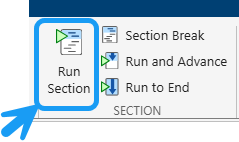 

## 1) Setup `PythonOCC` environment

**Instructions**

In this first step, you will load the Python™ environment that contains all needed functions to use PythonOCC from MATLAB®. Please note that the first time you run this section, the installation of `PythonOCC` may take up to approximately one minute. 

**Load the** `PythonOCC` **environment and install custom functions**

clear, geometryFunctions = env_conf;

**Setup geometry** `PythonOCC` **object**

fileName = fullfile(".", "geometry", "swingarm brep.igs");
geometryObj = geometryFunctions.MyApp();
geometryObj.readGeometryFile(fileName)

  Run this section of code by using "Run Section" in the toolstrip or clicking the "Run Code Section" button below:

## 2) Select Edge for Update

Using `PythonOCC` you can select any edges or control points to start modifying the geometry. To limit choices during this workshop, you will have a subset of 3 edges to choose from, and you can use the dropdown list in the code below to select the edge of the geometry you would like to update. Use the screenshots below as reference for the three different edges that can be modified. 

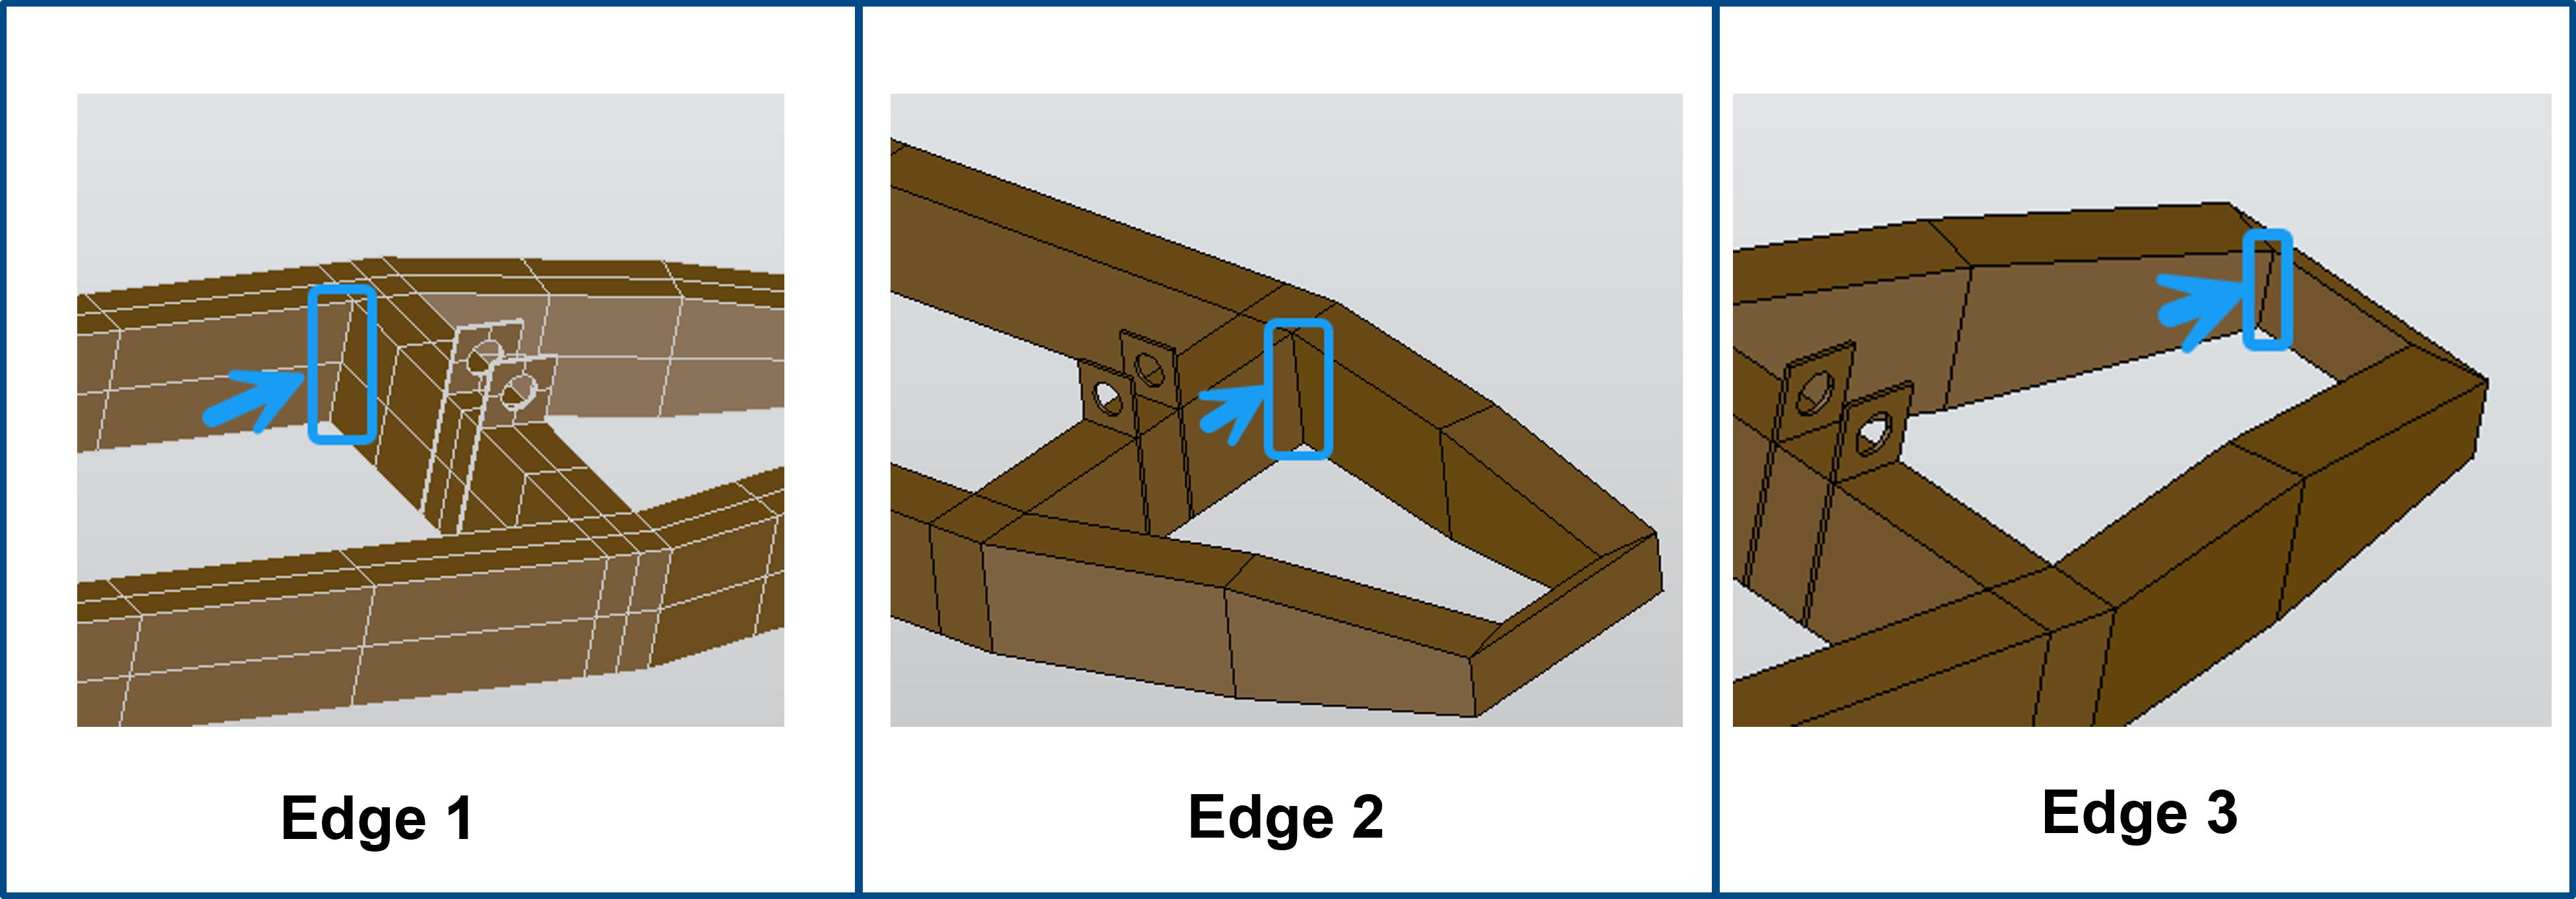

  Select an element from the dropdown list below. Note this Section will run automatically once you make a selection.

edgeID = 34;
geometryObj.selectedEdges = py.list([]);
selectedEdge = getSelectedEdge(geometryObj.baseShape, edgeID);
geometryObj.selectedEdges.append(selectedEdge)
geometryObj.getDataDesignVariables(py.int(0))
geometryObj.computeNumDesignVariables()
displaySelection(edgeID)

## 3) Change the Geometry by Performing a Design Update

Please make sure that Section 2 has been executed successfully and that variable `selectedEdge` exists in the base workspace with a `TopoDS_Edge` datatype

 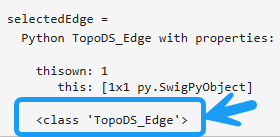 (hover your mouse over this variable here to view its value). Note that this `TopoDS_Edge` datatype is a `PythonOCC` datatype embedded in MATLAB®!

Now you will **update the shape based on the design update of the selected edge. Use the slider below to set the value. **Note this section will run automatically once you move the slider to a new position

  Use the slider to define the magnitude of the design change for the selected edge: 

d =0; % [cm]
geometryObj.updateShape(py.list(num2cell(d)));
geometryObj.updatedShape;

Compute the new angle between the adjacent faces of the selected edge (important measure used as constraint for the optimization)

dataNormals = geometryObj.getNormalsOnFacesAdjacentToSelectedEdges(geometryObj.updatedShape);
thetaUpdated = computeAngleBetweenAdjacentFaces(dataNormals)

**Create a solid from the updated B-Rep shape using PythonOCC functionalities**

Use custom function `createSolidFromBRepCompound` based on `PythonOCC` to create a solid geometry of type `TopoDS_Solid`

pyTuple = geometryFunctions.createSolidFromBRepCompound(geometryObj.updatedShape);

Export the solid geometry `TopoDS_Solid` stored into a PythonOCC datatype to file using custom function `writeGeometryToFile` based on `PythonOCC`

fileNameUpdated = fullfile('.', 'metadata', 'swingarm brep updated.step');
geometryFunctions.writeGeometryToFile(fileNameUpdated, pyTuple{1})

Read-in the `STEP`-file of the geometry in MATLAB® and visualize the geometry using the Partial Differential Equation Toolbox™

structModel = femodel(AnalysisType="structuralStatic", Geometry=fileNameUpdated);
pdegplot(structModel, EdgeLabels="off", FaceLabels="off", FaceAlpha=1)

  Rotate the generated shape to view the change you applied! Is the new design better than the previous one or not and why?

## 4) Perform Structural Analysis for the Updated Design and Postprocess the Results

  **Instructions**

- Run this section using the "Run" button below

- Navigate to Section Postprocessing and review the Visualize Live Task. Use the dropdown list "Select results" to select the variable containing the results you computed from the previous Section Set Material Properties, Apply Boundary Conditions and Solve the Structural Problem.

- Under the Section "Data Parameters" in the Visualize Live Task select Stress as "Type" and "von Mises" as "Component" to visualize the von Mises stresses across the swingarm. What do you observe regarding the stress concentration as the selected edge becomes less sharp throughout the design updates? What does your observation align with the value for the resulting strain energy you are obtaining here?

- Obseve the value of the strain energy for the updated swingarm design. Is it better or worse than the original design and why?

**Perform Structural Analysis for the Updated Design**

Appy material properties

structModel.MaterialProperties = materialProperties(YoungsModulus=200e9, ...
                                                    PoissonsRatio=0.28, ...
                                                    MassDensity=7800);

Apply Dirichlet and Neumann boundary conditions

structModel = applyBoundaryConditions(structModel);

Mesh the geometry

try
    structModel = generateMesh(structModel, "Hmax", 0.02, "Hmin", 0.005);
    pdemesh(structModel)
catch ME
    warning("Your design update %d created a geometry that cannot be meshed. " + ...
        "Please choose another value and inspect the resulting geometry in Section 3)" + ...
        "Address this issue before looking at any other error messages below", d)
end

Solve the problem

results = solve(structModel);

**Visualize of the von Mises stresses across the motorcycle swingarm**

**Compute the strain energy**

femMatrices = assembleFEMatrices(structModel);
dispVct = [results.Displacement.ux; results.Displacement.uy; results.Displacement.uz];
strainEnergy = transpose(dispVct)*femMatrices.K*dispVct;
disp("Strain Energy for the updated swingarm design is equal to: " + strainEnergy + " [Nm]")

**When you complete Example 3:**

**Continue to** [**Example 4**](matlab:open('./Example4.mlx')) **or back to** [`Main.mlx`](matlab:open('./Main.mlx'))

*Copyright 2025 The MathWorks, Inc.*